% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc; 
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-07-16/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Blood_Plasma(40x,495mW,CG)_2500_24_2024-07-16-17.30.45.390.csv";
file_path = data_path+file_name;
blood_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma2(40x,495mW,CG)_2500_24_2024-07-16-17.34.17.403.csv";
file_path = strcat(data_path,file_name);
blood_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma3(40x,495mW,CG)_2500_24_2024-07-16-17.36.52.490.csv";
file_path = strcat(data_path,file_name);
blood_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma4(40x,495mW,CG)_2500_24_2024-07-16-17.39.44.847.csv";
file_path = strcat(data_path,file_name);
blood_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma5(40x,495mW,CG)_2500_24_2024-07-16-17.42.28.170.csv";
file_path = strcat(data_path,file_name);
blood_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma6(40x,495mW,CG)_2500_24_2024-07-16-17.45.13.607.csv";
file_path = strcat(data_path,file_name);
blood_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma7(40x,495mW,CG)_2500_24_2024-07-16-17.47.59.203.csv";
file_path = strcat(data_path,file_name);
blood_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma8(40x,495mW,CG)_2500_24_2024-07-16-17.50.32.927.csv";
file_path = strcat(data_path,file_name);
blood_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma9(40x,495mW,CG)_2000_24_2024-07-16-17.53.48.730.csv";
file_path = strcat(data_path,file_name);
blood_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Blood_Plasma10(40x,495mW,CG)_2000_24_2024-07-16-17.55.52.113.csv";
file_path = strcat(data_path,file_name);
blood_10 = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [blood_6(1, 1:3101) ; nist1(23:end, :)];

file_name = "Polystyrene(40x,495mW)_70_100_2024-07-16-15.45.20.927.csv";
file_path = strcat(data_path,file_name);
poly1 = csvread(file_path, numMetadataRows, 0);
poly = mean(poly1(2:end,:));

file_name = "Silicon(40x,495mW)_60_100_2024-07-16-15.41.03.040.csv";
file_path = strcat(data_path,file_name);
Si1 = csvread(file_path, numMetadataRows, 0);
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = blood_1(1,:);

% trimming standard sample data to these WN's
t1 = 500;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
blood_1(:, blood_1(1, :) <= t1) = [];
blood_1(:, blood_1(1, :) >= t2) = [];
blood_2(:, blood_2(1, :) <= t1) = [];
blood_2(:, blood_2(1, :) >= t2) = [];
blood_3(:, blood_3(1, :) <= t1) = [];
blood_3(:, blood_3(1, :) >= t2) = [];
blood_4(:, blood_4(1, :) <= t1) = [];
blood_4(:, blood_4(1, :) >= t2) = [];
blood_5(:, blood_5(1, :) <= t1) = [];
blood_5(:, blood_5(1, :) >= t2) = [];
blood_6(:, blood_6(1, :) <= t1) = [];
blood_6(:, blood_6(1, :) >= t2) = [];
blood_7(:, blood_7(1, :) <= t1) = [];
blood_7(:, blood_7(1, :) >= t2) = [];
blood_8(:, blood_8(1, :) <= t1) = [];
blood_8(:, blood_8(1, :) >= t2) = [];
blood_9(:, blood_9(1, :) <= t1) = [];
blood_9(:, blood_9(1, :) >= t2) = [];
blood_10(:, blood_10(1, :) <= t1) = [];
blood_10(:, blood_10(1, :) >= t2) = [];

shifts = wavenumber;

blood1 = blood_1(2:end, :);
blood2 = blood_2(2:end, :);
blood3 = blood_3(2:end, :);
blood4 = blood_4(2:end, :);
blood5 = blood_5(2:end, :);
blood6 = blood_6(2:end, :);
blood7 = blood_7(2:end, :);
blood8 = blood_8(2:end, :);
blood9 = blood_9(2:end, :);
blood10 = blood_10(2:end, :);

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

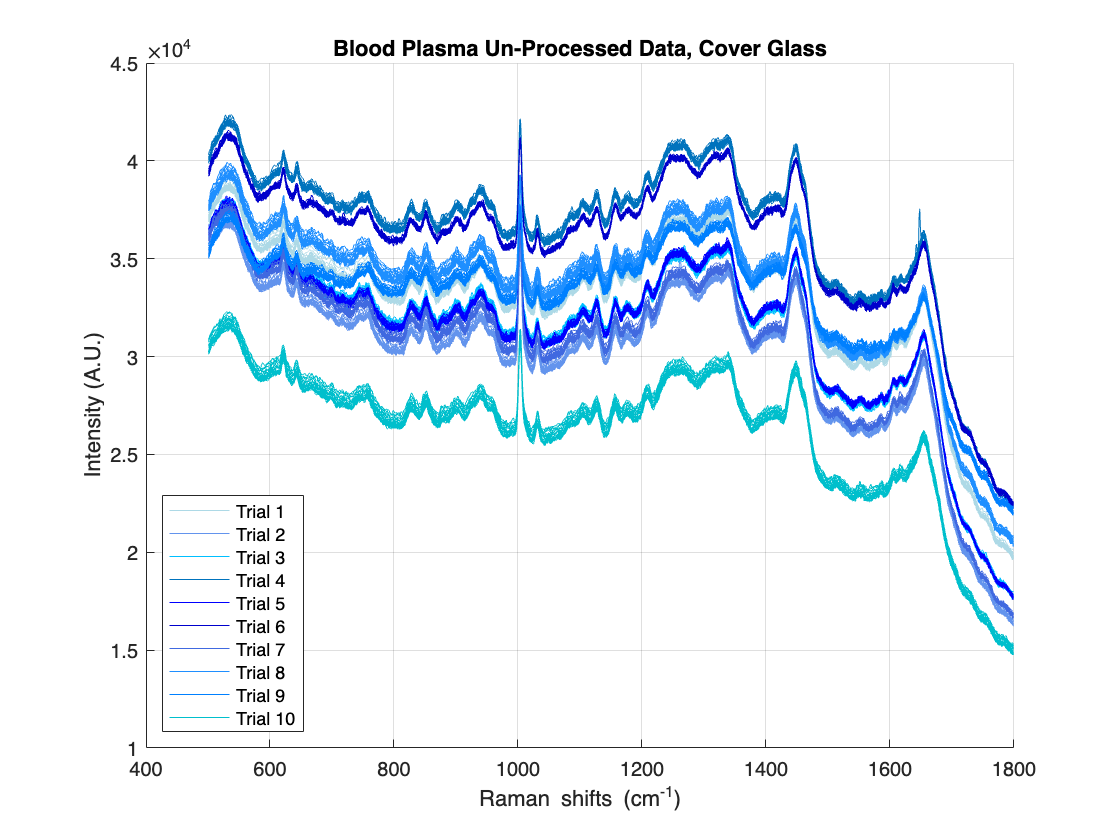

% Plotting unprocessed data

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, blood1(1,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(1,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(1,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(1,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(1,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(1,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(1,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(1,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(1,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(1,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

plot(wavenumber, blood1(2:end,:), 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, blood2(2:end,:), 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, blood3(2:end,:), 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, blood4(2:end,:), 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, blood5(2:end,:), 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, blood6(2:end,:), 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, blood7(2:end,:), 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, blood8(2:end,:), 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, blood9(2:end,:), 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, blood10(2:end,:), 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Blood Plasma Un-Processed Data, Cover Glass');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'location', 'southwest');
hold off;

% Preprocessing the data

% pro_blood1 = apply(blood1, [6,1,10,11,8,2,5,6,7]);
% pro_blood2 = apply(blood2, [6,1,10,11,8,2,5,6,7]);
% pro_blood3 = apply(blood3, [6,1,10,11,8,2,5,6,7]);
% pro_blood4 = apply(blood4, [6,1,10,11,8,2,5,6,7]);
% pro_blood5 = apply(blood5, [6,1,10,11,8,2,5,6,7]);
% pro_blood6 = apply(blood6, [6,1,10,11,8,2,5,6,7]);
% pro_blood7 = apply(blood7, [6,1,10,11,8,2,5,6,7]);
% pro_blood8 = apply(blood8, [6,1,10,11,8,2,5,6,7]);
% pro_blood9 = apply(blood9, [6,1,10,11,8,2,5,6,7]);
% pro_blood10 = apply(blood10, [6,1,10,11,8,2,5,6,7]);

% Checking for processing full dataset at once vs individual

blood = [blood1;blood2;blood3;blood4;blood5;blood6;blood7;blood8;blood9;blood10];
pro_blood = apply(blood, [6,1,10,8,2,5,6,7]);

[snr, closestShift] = SNR_loc(pro_blood, corr_shifts, 1003);
snr

snr =      1.021561570011901e+02


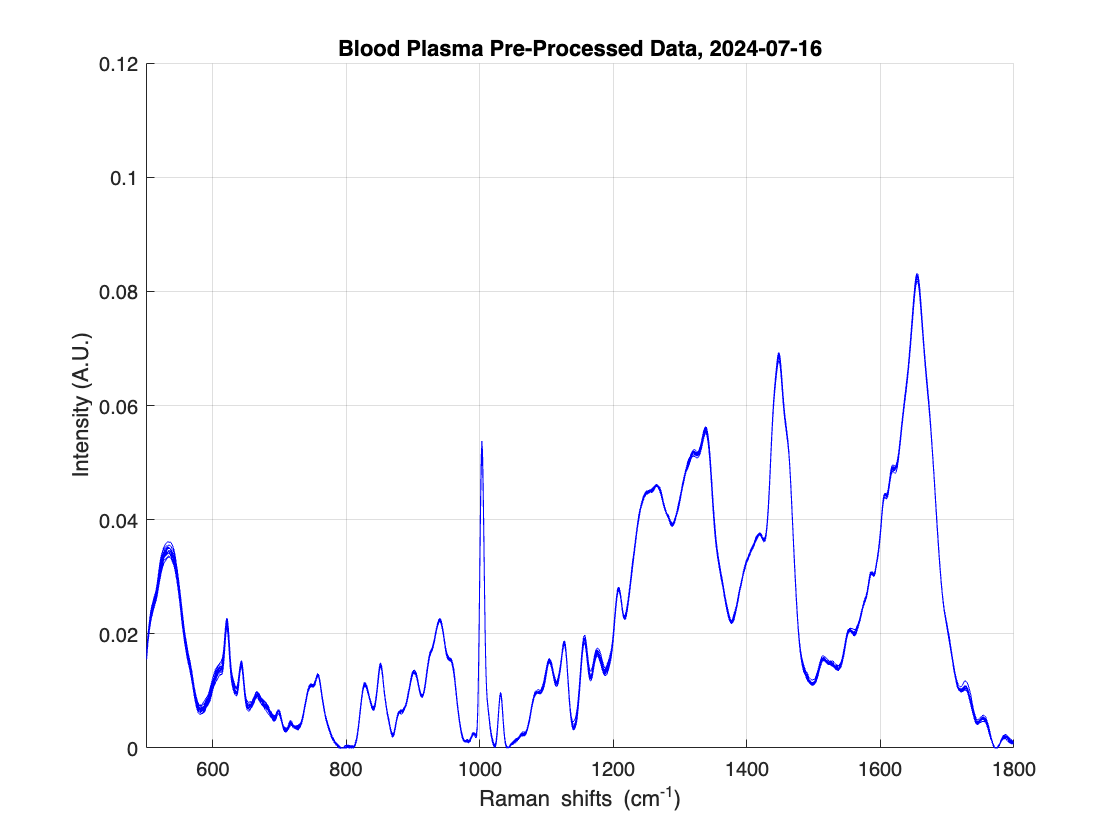


% Plotting pre-processed data

figure;
hold on;
grid on;
plot(wavenumber, pro_blood, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data, 2024-07-16');
xlim([500 1800]);
ylim([0 0.12]);
hold off;

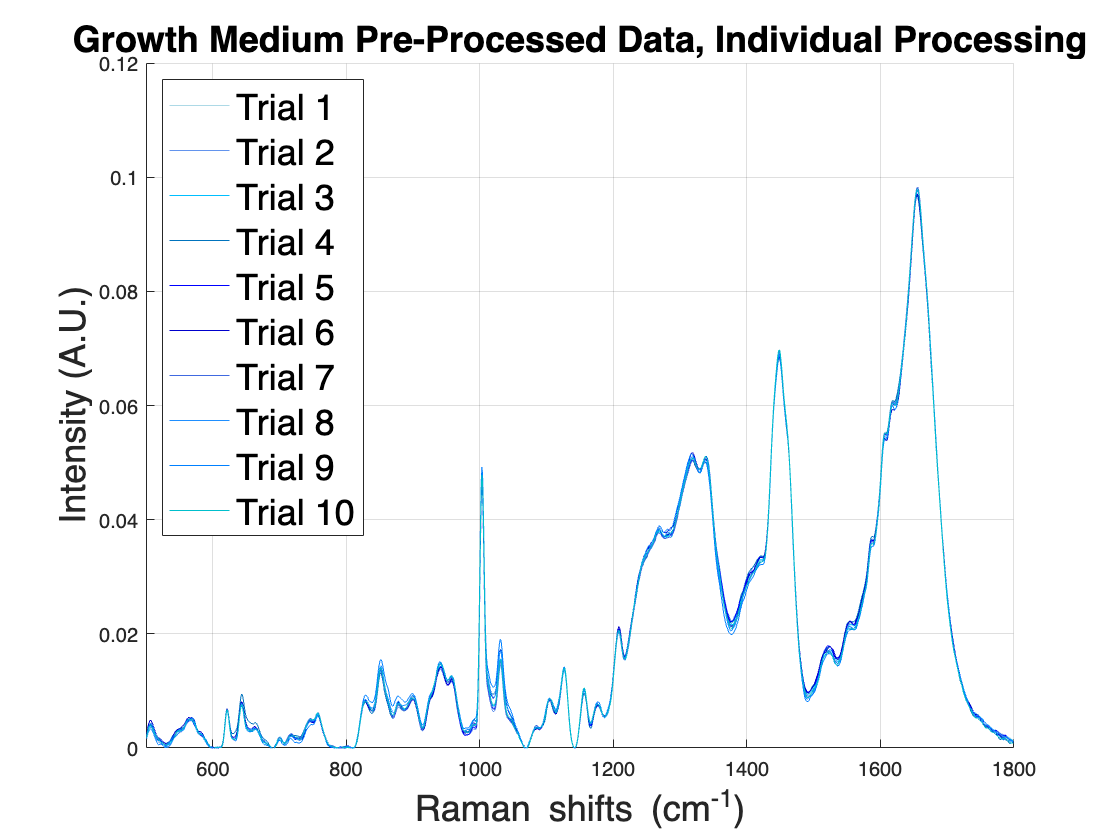

figure;
hold on;
grid on;

% Different shades of blue for the plots
plot(wavenumber, pro_blood1, 'Color', [0.68, 0.85, 0.90]); % Light Blue
plot(wavenumber, pro_blood2, 'Color', [0.39, 0.58, 0.93]); % Cornflower Blue
plot(wavenumber, pro_blood3, 'Color', [0.00, 0.75, 1.00]); % Deep Sky Blue
plot(wavenumber, pro_blood4, 'Color', [0.00, 0.45, 0.74]); % Royal Blue
plot(wavenumber, pro_blood5, 'Color', [0.00, 0.00, 1.00]); % Blue
plot(wavenumber, pro_blood6, 'Color', [0.00, 0.00, 0.80]); % Navy
plot(wavenumber, pro_blood7, 'Color', [0.25, 0.41, 0.88]); % Dodger Blue
plot(wavenumber, pro_blood8, 'Color', [0.12, 0.56, 1.00]); % Light Sky Blue
plot(wavenumber, pro_blood9, 'Color', [0.00, 0.50, 1.00]); % Blue
plot(wavenumber, pro_blood10, 'Color', [0.00, 0.75, 0.80]); % Dark Turquoise

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
title('Growth Medium Pre-Processed Data, Individual Processing');
legend('Trial 1','Trial 2','Trial 3','Trial 4','Trial 5','Trial 6','Trial 7','Trial 8','Trial 9','Trial 10', 'Location', 'northwest');
hold off;

fulldata = readmatrix('Data/Training_Compact_May_2023.csv');
n = 10; % donor number
% 10 donors donor ID's
% D1-186 D2-191 D3-102 D4-86 D5-192 D8-77 D9-195 D10-123 D11-196 D12-197
don = [186, 191, 102, 86, 192, 77, 195, 123, 196, 197];
 
% trimming blood plasma data and standard samples data to these WN's
t1 = 500;
t2 = 1800;

data_1 = fulldata;  
data_1(:, data_1(1, :) <= t1) = [];
data_1(:, data_1(1, :) >= t2) = [];
data_1 = [[fulldata(:, 1:3)] data_1];

shifts = data_1(1, 4:end);

% import standard sample data and take average to use for Raman shift
% correction and NIST correction
poly1 = readmatrix('Data/Polystyrene_1_2024-05-07-10.40.30.583.csv'); 
poly = mean(poly1(2:end,:));

Si1 = readmatrix('Data/Silicon_2_2024-05-07-10.25.23.800.csv'); 
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [fulldata(1, 4:end) ; nist1(23:end, :)];
NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

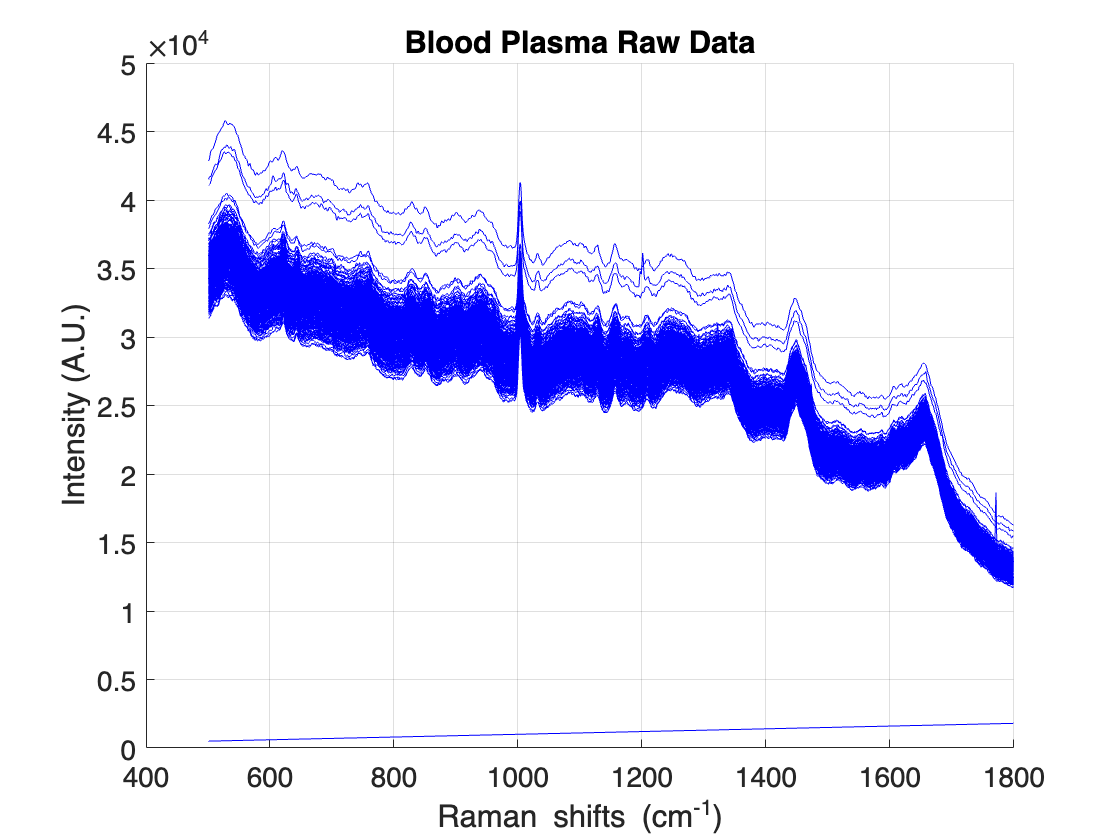

% PREPROCESSING THE DATA

[all, train, test] = prepSet(data_1, don(n), -1, -1, [6,1,10,11,8,2,5,6,7]);
prep = [0 0 0 shifts ;  all];
data1 = data_1(data_1(:, 2) == 0, 4:end);
data1 = data1(2,:);

% PLOTS OF THE RAW AND PREPROCESSED DATA

fig1 = figure;
ax1 = axes(fig1);
grid on;
hold on;
plot(ax1, shifts, data_1(data_1(:, 2) == 0, 4:end), 'b')
xlabel(ax1, 'Raman shifts (cm^{-1})')
ylabel(ax1, 'Intensity (A.U.)')
title('Blood Plasma Raw Data')
ax1.FontSize = 14;
hold off;

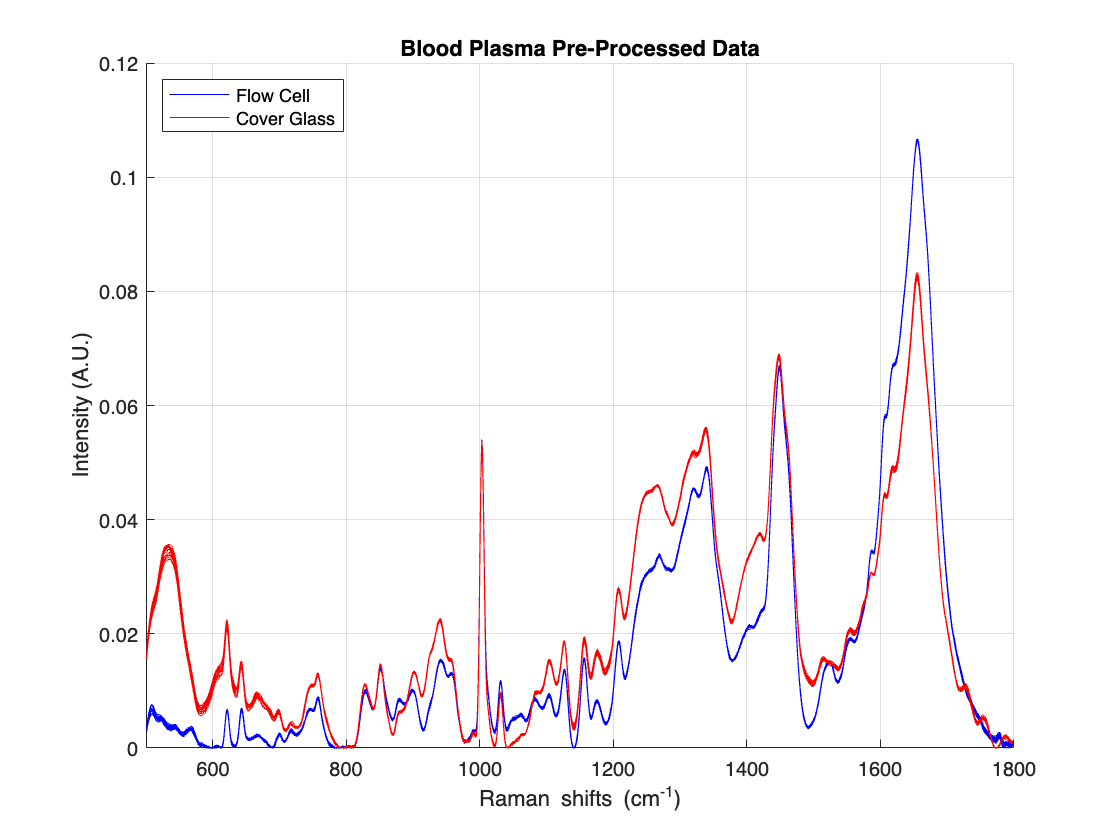

flow_processed = all(all(:, 2) == 1, 4:end);
figure;
grid on;
hold on;
plot(shifts, flow_processed(1,:), '-b');
plot(wavenumber, pro_blood(1,:), '-r');
plot(shifts, flow_processed(2:end,:), '-b')
plot(wavenumber, pro_blood(2:end,:), '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Blood Plasma Pre-Processed Data');
xlim([500 1800]);
ylim([0 0.12]);
legend('Flow Cell','Cover Glass','Location', 'northwest');
hold off;

function [t_val, p_val, df] = perform_ttest(av1, av2, std1, std2, n1, n2)
    t_val = abs((av1 - av2) / sqrt((std1^2 / n1) + (std2^2 / n2)));
    df = ((std1^2 / n1) + (std2^2 / n2))^2 / ...
         (((std1^2 / n1)^2 / (n1 - 1)) + ((std2^2 / n2)^2 / (n2 - 1)));
    p_val = 2 * (1 - tcdf(abs(t_val), df));
end

function [snr, closestShift] = SNR_loc(spectra, shifts, wavenumber)

    [~, closestIndex] = min(abs(shifts - wavenumber));

    closestShift = shifts(closestIndex);

    peaks = spectra(:, closestIndex);

    snr = mean(peaks)/std(peaks);

end

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end




